Author： 黃仕鈞

# Reclaim the Autoregressive Model

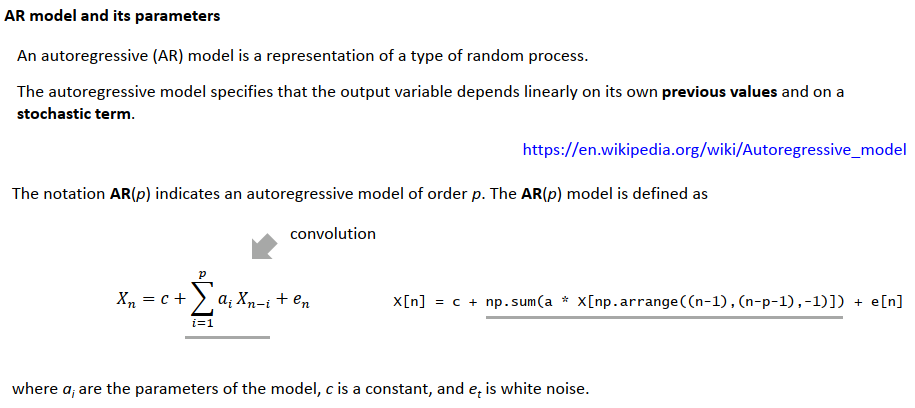

NBE_Aalto University_neuroscience_course

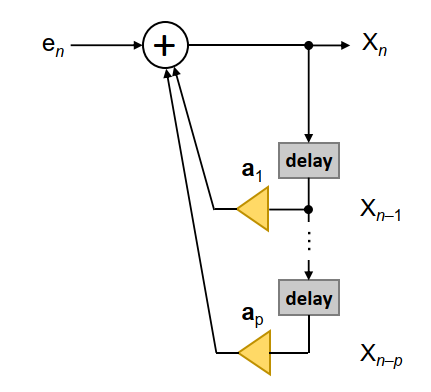


$$X_n =c+\sum_{i=1}^p a_i X_{n-i} +e_n$$


# Distortion Rate

[RATE DISTORTION STUDY FOR TIME-VARYING AUTOREGRESSIVE GAUSSIAN PROCESS](https://arxiv.org/abs/1910.14228)


$$x_t =-\sum_{m=1}^M a_m \left(r\right)x_{t-m} +z_t ,\;\textrm{for}\;t=1,2,\dots ,N$$


- $r=\;\frac{t}{N}$  is defined as distortion rate.


$$g(r,\omega )=\frac{1}{\sigma_z^2 }{\left|1+\sum_{m=1}^M a_m (r)e^{-jm\omega } \right|}^2$$


Use [Anonymous Function](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) + ( f[ucntion](https://www.mathworks.com/help/matlab/ref/function.html), or insert by [struct](https://www.mathworks.com/help/matlab/ref/struct.html))  and set the integral description.

Use [str2func](https://www.mathworks.com/help/matlab/ref/str2func.html), sprintf( str1+str2) to implement it,

 [Python use the ways like the dictionary](https://stackoverflow.com/questions/10303248/true-dynamic-and-anonymous-functions-possible-in-python).. and str = str1+str2.

And a important skill is add generator string to Anonymous Fcn, design it for nested loops.

$D_{\theta } =\frac{1}{2\pi }\int_{-\pi }^{\pi } \int_0^1 \mathrm{min}\left\lbrack \theta ,\frac{1}{g(r,\omega )}\right\rbrack drd\omega$, iteration > 1, need past value

- $\theta$ is upper threshold, set to 0.1 close to 0

$R\left(D_{\theta } \right)=\frac{1}{2\pi }\int_{-\pi }^{\pi } \int_0^1 \mathrm{max}\left\lbrack 0,\frac{1}{2}\mathrm{log}\frac{1}{\theta \times (r,\omega )}\right\rbrack drd\omega$, iteration >1, need past value

-  0 is low limit

clear all; clc;
% parameter
N = 7; % quantity of samples
e = randn(N);
e = e / max(e);

% es = sin((1:N))+ sin((1:N).*2+10); % add sin sin wave
% e = 1./6.*(es'+e); % es' is transpose result of es

a = [];
sets = 5; % test sets
lag = 5; % AR(p) p is lag
% (N-lag)>=2 need to be true(==1), '>1' -> lag ,'>2' integral

% Generate the a(r) AR is not able to linear regression but just test
% time varying a --> design varying a
for i = 1:N
    a(i) = (i/N); 
end
ac = zeros(sets,1); % index sets with constant
ac = [0.1, 0.9, -0.9 ,0.3, 0.5]; % constant close to 0, 1...

x = zeros(N,sets);
xc = zeros(N,sets); % 初始化矩陣大小 constant

for j =1:lag % lag not calc
    for i = 1:5 % which data
        x(j,i) = 0; % a(i).*x(j,i)+e(j);
        xc(j,i) = 0; % ac(i).*x(j,i)+e(j);
    end
end
sigma = zeros(1,N); theta = zeros(1,N); r = zeros(1,N); omega = zeros(1,N);
g = zeros(1,N); xx = zeros(1,N); nn = zeros(1,N);
for j = 1:sets % lag+1 這裏只有一筆資料，無法積分
    i = lag+1;
    xc(i,j) = ac(j).*x(i,j)+e(i); % 對照組 constant a
    x(i,j) = a(i).*x(i,j)+e(i);
    % clac initial g value
    g_struct = struct('sets_index_now',j,'data_index_now',i,'lag_p',lag,...
            'samples',N, 'varing_gain',a,'predict',x,'noise',e.*0.9,'input',e );
    sigma(i) = var(g_struct.predict(:,1)); % get the varience
    theta(i) = max(g_struct.predict(:,1)) - sigma(i)./4; % 暫時這麼算 上限 upper threshold
    r(i) = g_struct.varing_gain(i);
    omega(i) = 2.71828;
    x_in = g_struct.predict(:,1);% x(:,1), x(:,2) is the same...
    g(i) = 1./(sigma(i).^2).* abs(1 + sum(1 + x_in.*exp(-j.*length(N-lag+1).*omega(i)))).^2;% omega暫時用2.71828
end

% omega and m don't know the const values

for j = 1:sets % 這裏開始計算distortion rate N-lag-1 筆資料
    for i = (2+lag):N % calc start from AR(p->lag) --> lag+2
        xc(i,j) = ac(j).*x(i-lag,j)+e(i); % 對照組 constant a
        x(i,j) = a(i).*x(i-lag,j)+e(i);
        g_struct = struct('sets_index_now',j,'data_index_now',i,'lag_p',lag,...
            'samples',N, 'varing_gain',a,'predict',x,'noise',(e.*0.9), 'input',e );
        sigma(i) = var(g_struct.predict(:,1)); % get the varience
        theta(i) = max(g_struct.predict(:,1)) - sigma(i)./4; % 暫時這麼算 上限 upper threshold
        r(i) = g_struct.varing_gain(i);
        omega(i) = 2.71828;
        x_in = g_struct.predict(:,1);% x(:,1), x(:,2) is the same...
        % calc g value
        % searching the minimum of 1/g in our prediction values, O(n) sorting 算法可能更好
        g(i) = 1./(sigma(i).^2).* abs(1 + sum(1 + x_in.*exp(-j.*length(N-lag+1).*omega(i)))).^2;% omega暫時用2.71828
        % min(g(g~=0)) % g的最小數值
        %ind = find(g == min( g(g>0) ),1,'last'); % 偷吃步一下, 找曲線波動滿有用的
        k= 1./g;
        ind = find(k == min( k(k>0) ),1,'last');
        % g(ind) % g的最小值代入ind這一項
        %D_theta = @(r,w) 1./( 1./(sigma(i).^2).* abs(1 + sum(1 + s(i,:).*exp(-j.*length(s(i,:)).*w))).^2 );
        for lengths = 1:length(g_struct.predict(:,1))
            xx(i) = g_struct.predict(i,1);
            %nn = g_struct.noise(i,1);
            nn(i) = 0.212826888264831; % set to const now
            %r = g_struct.data_index_now(i)/g_struct.samples;
            r(i) = a(i);
        end
        str1 = '@(r,w)1./( 1./(';
        str2 = string(sigma(i));
        str3 = ').^2).*abs(1+(';
        for indd = 1:ind % strings of sum part
            list = ['((', string(a(i)), ').*r','+' , '(',string(nn(i)),')']; % x 要改成跟 r.*(輸入_const)+ noise_const
            str4 = sprintf( list(1)+list(2)+list(3) ); 
            str5 = ').*exp(-j.*(';
            str6 = string(indd); % exp(-j.*omega.*m) whatis m?
            str7 = ').*w)+';
            str8 = ').*w)';
            list_fn(indd) = sprintf(str4+str5+str6+str7);
            if indd == ind
                list_fn(indd) = sprintf(str4+str5+str6+str8);
            end
        end
        strff = '';
        for indd = 2:ind
            str9 = strff;
            strff = sprintf(str9+list_fn(indd-1)+list_fn(indd));
        end
        strfin = ').^2)';
        str_intgral_D = sprintf(str1+str2+str3+strff+strfin); % for D
        D_integral_fun = str2func(str_intgral_D); % struct()
        D = integral2(D_integral_fun, 0,1, -pi, pi);
        
        str11 = '@(r,w)1./2.*log(1.*';
        str12 = string(D); % multiple min value of 1/g -integral-> D (1/g), use D
        str13 = './( 1./('; 
        strfin = ').^2))';
        str1 = sprintf(str11+str12+str13);
        str_intgral_R  = sprintf(str1+str2+str3+strff+strfin);
        R_integral_fun = str2func(str_intgral_R); % struct()
        R = integral2(R_integral_fun, 0,1, -pi, pi);
        
    end
end
clearvars str11 str12 str13 str1 str2 str3 str4 str5 str6 str7 str8 str9 strff strfin list list_fn;
ind % use this minimum value in the final iteration

ind = 6

str_intgral_D % the last one integral calc

str_intgral_D = "@(r,w)1./( 1./(0.018065).^2).*abs(1+(((1).*r).*exp(-j.*(1).*w)+((1).*r).*exp(-j.*(2).*w)+((1).*r).*exp(-j.*(2).*w)+((1).*r).*exp(-j.*(3).*w)+((1).*r).*exp(-j.*(3).*w)+((1).*r).*exp(-j.*(4).*w)+((1).*r).*exp(-j.*(4).*w)+((1).*r).*exp(-j.*(5).*w)+((1).*r).*exp(-j.*(5).*w)+((1).*r).*exp(-j.*(6).*w)).^2)"

str_intgral_R % the last one integral calc

str_intgral_R = "@(r,w)1./2.*log(1.*0.013637./( 1./(0.018065).^2).*abs(1+(((1).*r).*exp(-j.*(1).*w)+((1).*r).*exp(-j.*(2).*w)+((1).*r).*exp(-j.*(2).*w)+((1).*r).*exp(-j.*(3).*w)+((1).*r).*exp(-j.*(3).*w)+((1).*r).*exp(-j.*(4).*w)+((1).*r).*exp(-j.*(4).*w)+((1).*r).*exp(-j.*(5).*w)+((1).*r).*exp(-j.*(5).*w)+((1).*r).*exp(-j.*(6).*w)).^2))"

D

D = 0.0136

R

R = -36.4264

% calc end %
% print the distortion rate of x(lag:N) t in [lag, N]


$$g(r,\omega )=\frac{1}{\sigma_z^2 }{\left|1+\sum_{m=1}^M a_m (r)e^{-jm\omega } \right|}^2$$



$$D_{\theta } =\frac{1}{2\pi }\int_{-\pi }^{\pi } \int_0^1 \mathrm{min}\left\lbrack \theta ,\frac{1}{g(r,\omega )}\right\rbrack drd\omega$$


- $\theta$ is upper threshold, set to 0.1 close to 0


$$R\left(D_{\theta } \right)=\frac{1}{2\pi }\int_{-\pi }^{\pi } \int_0^1 \mathrm{max}\left\lbrack 0,\frac{1}{2}\mathrm{log}\frac{1}{\theta \times (r,\omega )}\right\rbrack drd\omega$$


-  0 is low limit

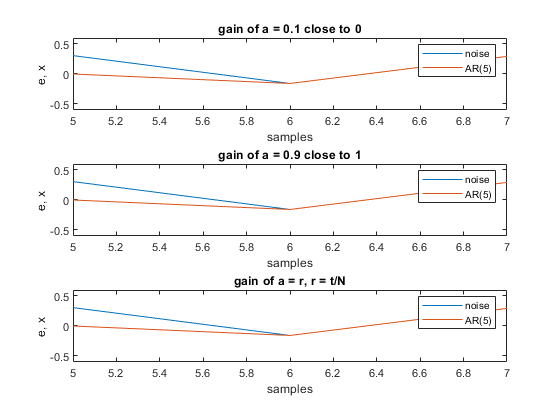

% Plot
str1 = ['AR', '(', string(lag), ')' ];
t = linspace(1,N,N);
ylimit_const = [-0.6, 0.6];
AR = sprintf( str1(1)+str1(2)+str1(3)+str1(4));

figure();
subplot(3, 1, 1);
plot(t(lag:end),e(lag:end));
hold on;
plot(t(lag:end),xc(lag:end,1));
title('gain of a = 0.1 close to 0');
xlim([lag, N]); %xlim(0, N);
ylim(ylimit_const); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', AR)
subplot(3, 1, 2);
plot(t(lag:end),e(lag:end));
hold on;
plot(t(lag:end),xc(lag:end,2));
title('gain of a = 0.9 close to 1')
xlim([lag, N]); %xlim(0, N);
ylim(ylimit_const); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', AR)
subplot(3, 1, 3);
plot(t(lag:end),e(lag:end));
hold on;
plot(t(lag:end),x(lag:end,1));
title('gain of a = r, r = t/N')
xlim([lag, N]); %xlim(0, N);
ylim(ylimit_const); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', AR)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%     Calc approach ways    %%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This block not calculate
% in 2020 MATLAB the function can be defined in the same file
% x(i,j) = a(i).*x(i-lag,j)+e(i);
% s = struct(field1,value1,field2,value2,field3,value3,field4,value4)
% field 儘量有意義一點
% call by s.field1 or s(1) it will get te value
% x(j,i) = a(i).*x(i-lag,j)+e(i); from this seris x(:,1)
s = x(:,1); % input_seris  x(:,1), x(:,2) is the same...
s = zeros(N-lag,N); % it's size initial
s(i,:) = x(:,1); % input_seris  x(:,1), x(:,2) is the same...
sigma(i) = var(x(:,1)); % get the varience
theta(i) = max(s(i,:)) - sigma(i)./4; % 暫時這麼算 上限 upper threshold
r(i) = a(i);
omega(i) = 2.71828;
% after summarize above
% we knoow it need i, j, lag, N, x, a, e,  for our calc integral
g_struct = struct('sets_index_now',j,'data_index_now',i,'lag_p',lag,...
    'samples',N,'predict',x,'noise',(e.*0.9),'input',e )

g_struct = struct with fields:
    sets_index_now: 5
    data_index_now: 7
             lag_p: 5
           samples: 7
           predict: [7×5 double]
             noise: [7×1 double]
             input: [7×1 double]


% searching the minimum of 1/g in our prediction values, O(n) sorting 算法可能更好
% g = zeros(2,2) % (i,g) store the index in g for 丟入參數再for找數字
% 再回去g_struct產生公式積分
%g = zeros(1,N);
%g(i) = 1./(sigma(i).^2).* abs(1 + sum(1 + s(i,:).*exp(-j.*length(s(i,:)).*omega(i)))).^2;% omega暫時用2.71828
% D function 其他略，看上面s的部分要用struct array 加上字串處理設計出積分的項並做成匿名函數，新的iter會多一項要積分
% ignore the D description
% function to get s's parameter in string
%D_theta = @(r,w) 1./( 1./(sigma(i).^2).* abs(1 + sum(1 + s(i,:).*exp(-j.*length(s(i,:)).*w))).^2 ); 
%D(i) = integral2(fun,0,1,-pi,pi);
%R(i) = integral2(fun,xmin,xmax,ymin,ymax);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# Matlab Deal the prob

Matlab Deal the prob with Anonymous Function (匿名函式), can solve the nested code. str2func

- [anonymous function   = @(x) exp(-x);      = @(x,y) exp(x)+y](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)

- [integral(anon_fun, -inf, inf)](https://www.mathworks.com/help/matlab/ref/integral.html)

- [integral2(anon_fun, -inf,inf,  -inf, inf) double integral](https://www.mathworks.com/help/matlab/ref/integral2.html)

>> str1 = '@(x)'

>> str2 =  'exp(-x.^2)'

>> str3 = '.*'

>> str4 = 'log(x).^2'

>> str5 =  [str1, str2, str3, str4]

str5 =

    '@(x)exp(-x.^2).*log(x).^2'

>> fun = str2func(str5)

fun =

  function_handle with value:

    @(x)exp(-x.^2).*log(x).^2

>> q = integral(fun,0,Inf)

q =

    1.9475

% 有變數要用 sprintf, 因爲 Matlab 好像，少執行了這塊

>> str1 = ['AR', '(', string(lag), ')' ]

str1 = 

  1×4 string array

    "AR"    "("    "30"    ")"

>> AR = sprintf( str1(1)+str1(2)+str1(3)+str1(4) )

AR = 

    "AR(30)"

# Integral Source may from:

```m

% [Trapezoidal numerical integration](https://www.mathworks.com/help/matlab/ref/trapz.html) to do it

y = sin(t)

trapz(t,y) %

trapz(x)  % x is meshgrid() result

%  inf -inf prob will failed

```

# MonteCarlo approach of the inf -inf prob

But can't deal the $\int_{-\infty }^{\infty } \frac{f(x)}{g(x)}$, if g(x) have log() or exp(), may have problems for me.

So try matlab first.

MonteCarlo may not meet the anwser for me.

目前只會用Matlab做這類積分, 因爲匿名函數整合的很好

可以想想如何用trapz做，pytorch出來之後可以

使用torch.meshgrid(), torch.trapz()，並使用GPU進行計算，

Pytorch厲害在可以使用AMD和NVIDIA GPU進行這些動作。

自己做的話，積分問題還不太瞭解做法。

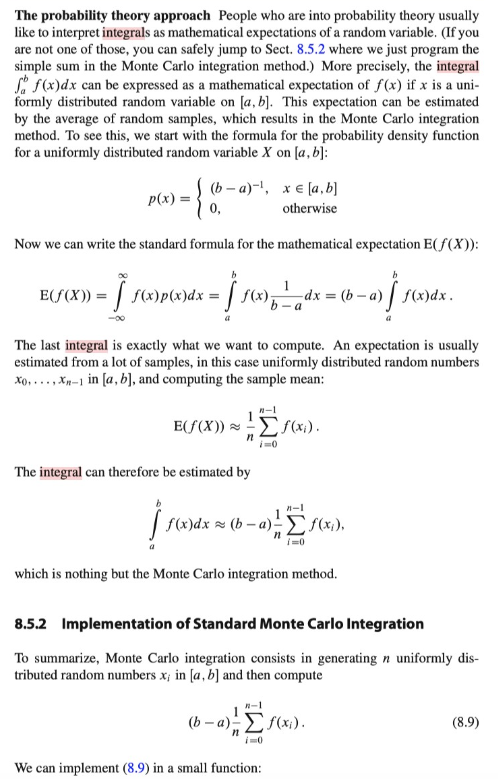

之前Llodmax 計算就會, （Llodmax I run before）

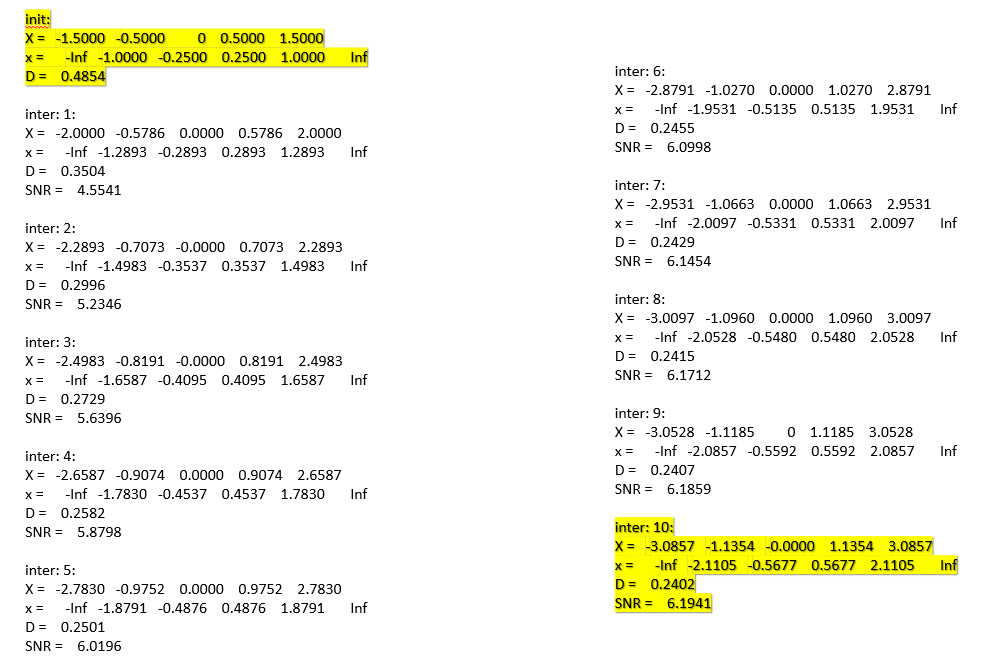

Run with trapz() and scipy.integral.quad(), still no good anwser.

trapz() 這種matlab會有同名function的庫有： 

Numpy、Cupy、Scipy、Pytorch   用於一些數值計算

其中Pytorch最近很紅，因爲開始支援AMD & NVIDIA GPU以往都很多限制。 

例如：Cupy似乎每個指令之間仍有所延遲，還有CPU、GPU計算比重，效能沒有想像中的好，而且只有NVIDIA可用。